**b) Plot the energy vs q along certain directions: going from M to **$\Gamma$** , then from **$\Gamma$**to X, then from X back to M (This will be a 2D plot.)**

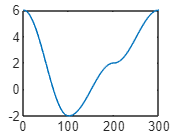

clc
clear
close all

qx = linspace(-pi, pi, 100);  % k_x space
qy = linspace(-pi, pi, 100);  % k_y space
[QX, QY] = meshgrid(qx, qy);

M = [pi, pi];
X = [pi, 0];
Gamma = [0, 0];
Es = 2; % eV
gamma = -1; % eV

k_MG = [linspace(M(1), Gamma(1), 100)', linspace(M(2), Gamma(2), 100)'];
k_GX = [linspace(Gamma(1), X(1), 100)', linspace(Gamma(2), X(2), 100)'];
k_XM = [linspace(X(1), M(1), 100)', linspace(X(2), M(2), 100)'];

E_MG = Es + 2*gamma * cos(k_MG(:,1)) + 2*gamma * cos(k_MG(:,2));
E_GX = Es + 2*gamma * cos(k_GX(:,1)) + 2*gamma * cos(k_GX(:,2));
E_XM = Es + 2*gamma * cos(k_XM(:,1)) + 2*gamma * cos(k_XM(:,2));

E = [E_MG; E_GX; E_XM];
E = E(:);

plot(E);

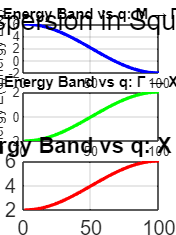


figure;

% M -> Gamma
subplot(3,1,1);
plot(E_MG, 'b', 'LineWidth', 2);
title('Energy Band vs q: M → Γ');
ylabel('Energy E(q)');
grid on;

% Gamma -> X
subplot(3,1,2);
plot(E_GX, 'g', 'LineWidth', 2);
title('Energy Band vs q: Γ → X');
ylabel('Energy E(q)');
grid on;

% X -> M
subplot(3,1,3);
plot(E_XM, 'r', 'LineWidth', 2);
title('Energy Band vs q: X → M');
xlabel("q (Reciprocal space)");
ylabel('Energy E(q)');
grid on;

% Adjust layout for better readability
sgtitle('Energy Dispersion in Square Lattice', 'FontSize', 16);
set(gca, 'FontSize', 12);
set(gcf, 'Position', [100, 100, 600, 800]);